# **Characterising Song Notes**

## **Note space for four species of Wren-Warblers**

#### **Observing note spaces**

load('song_space.mat')
load('visual_clustering_from_spectrogram.mat')
scorea = score(labelled_song_data(:,end)==1,:); scoreg = score(labelled_song_data(:,end)==2,:); ...
    scorej = score(labelled_song_data(:,end)==3,:); scorep = score(labelled_song_data(:,end)==4,:);
songNTa = songNT(labelled_song_data(:,end)==1,:); songNTg = songNT(labelled_song_data(:,end)==2,:); ...
    songNTj = songNT(labelled_song_data(:,end)==3,:); songNTp = songNT(labelled_song_data(:,end)==4,:);

### **Ashy Prinia Note Space**

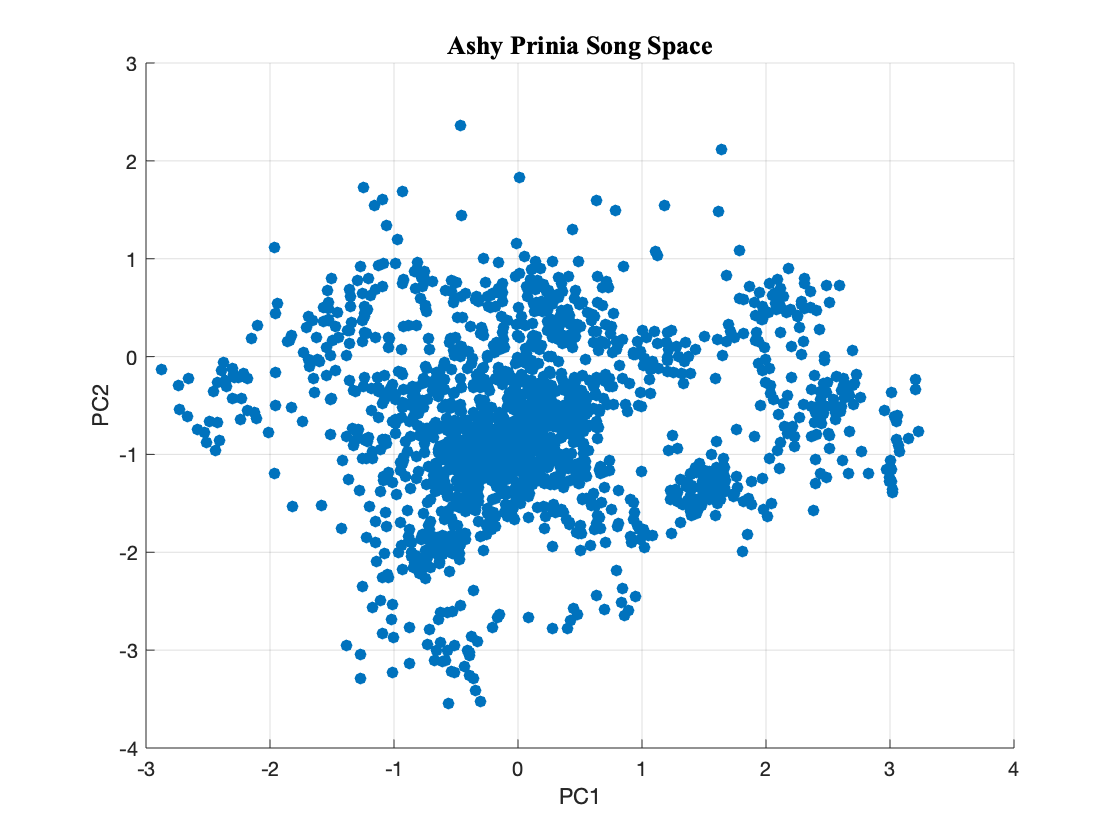

clf;
scatter(scorea(:,1),scorea(:,2), 'filled');
xlabel('PC1'); ylabel('PC2');
grid on;
title('Ashy Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

**Annotated Clusters**

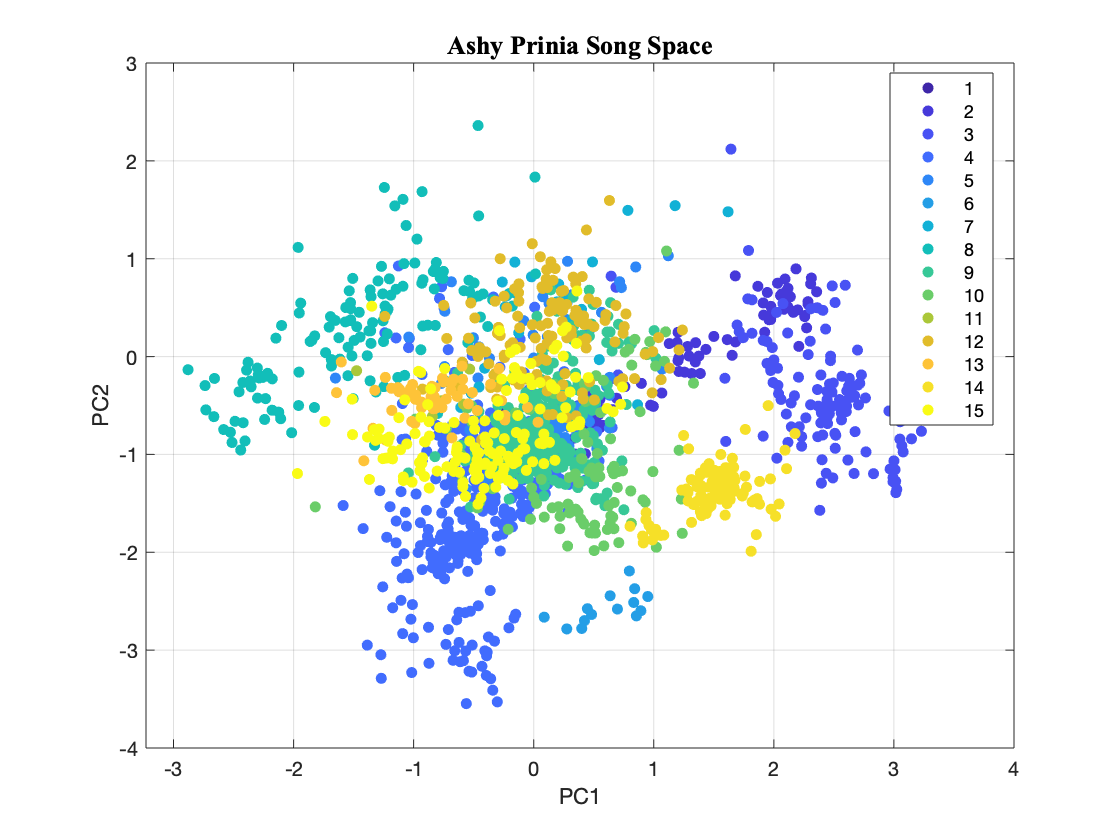

songNTa = indexer(songNTa);
gscatter(scorea(:,1),scorea(:,2),songNTa,parula(length(unique(songNTa))),[],15);
xlabel('PC1'); ylabel('PC2');
grid on;
title('Ashy Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

**Clubbing Note Types visually to get main clusters (Visual clustering based on spectrograms)**

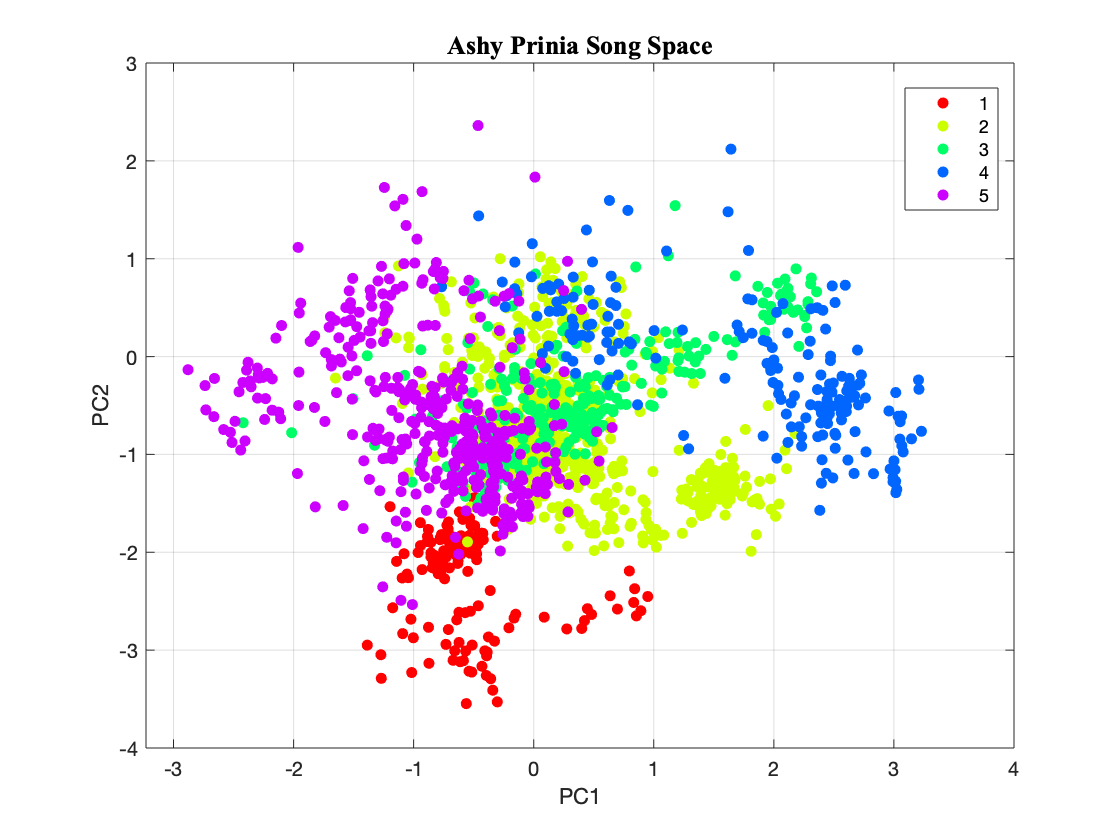

gscatter(scorea(:,1),scorea(:,2),Ta,hsv(length(unique(Ta))),[],15);
xlabel('PC1'); ylabel('PC2');
grid on;
title('Ashy Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

**Hierarchical Clustering**

Since we see instance of clustering, we will perform unsupervised clustering on this dataset

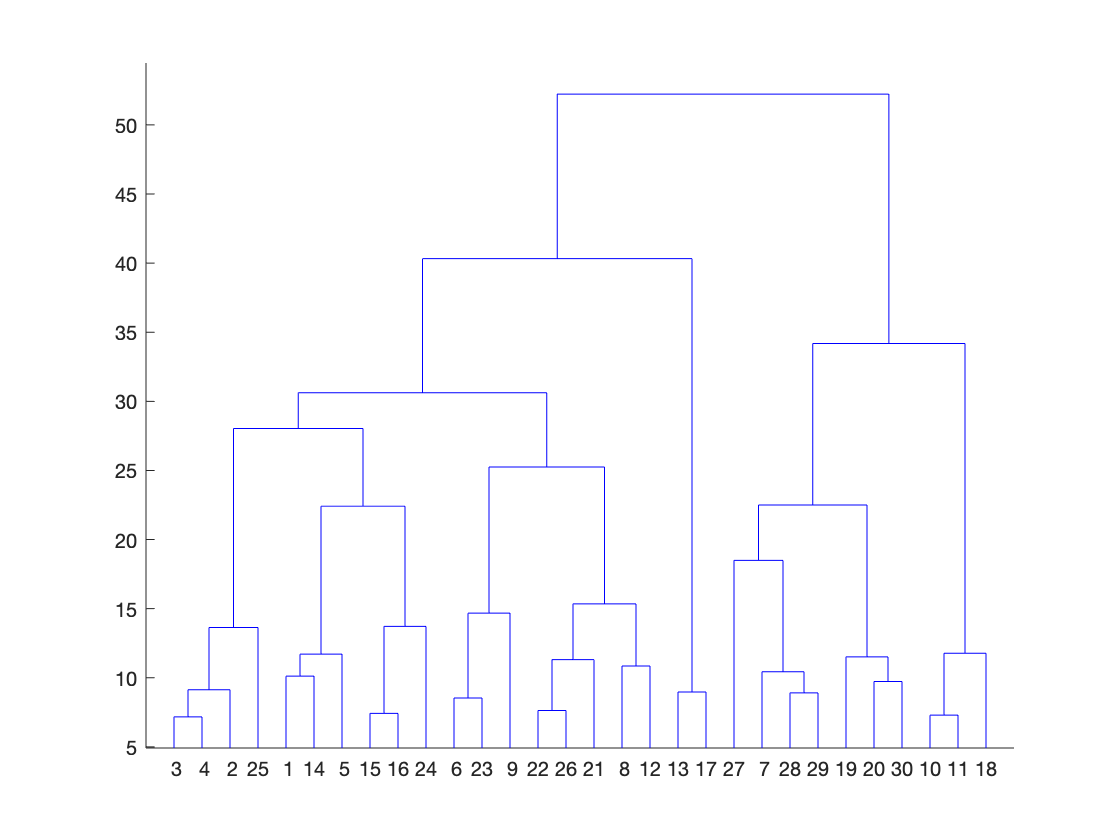

dend(scorea);

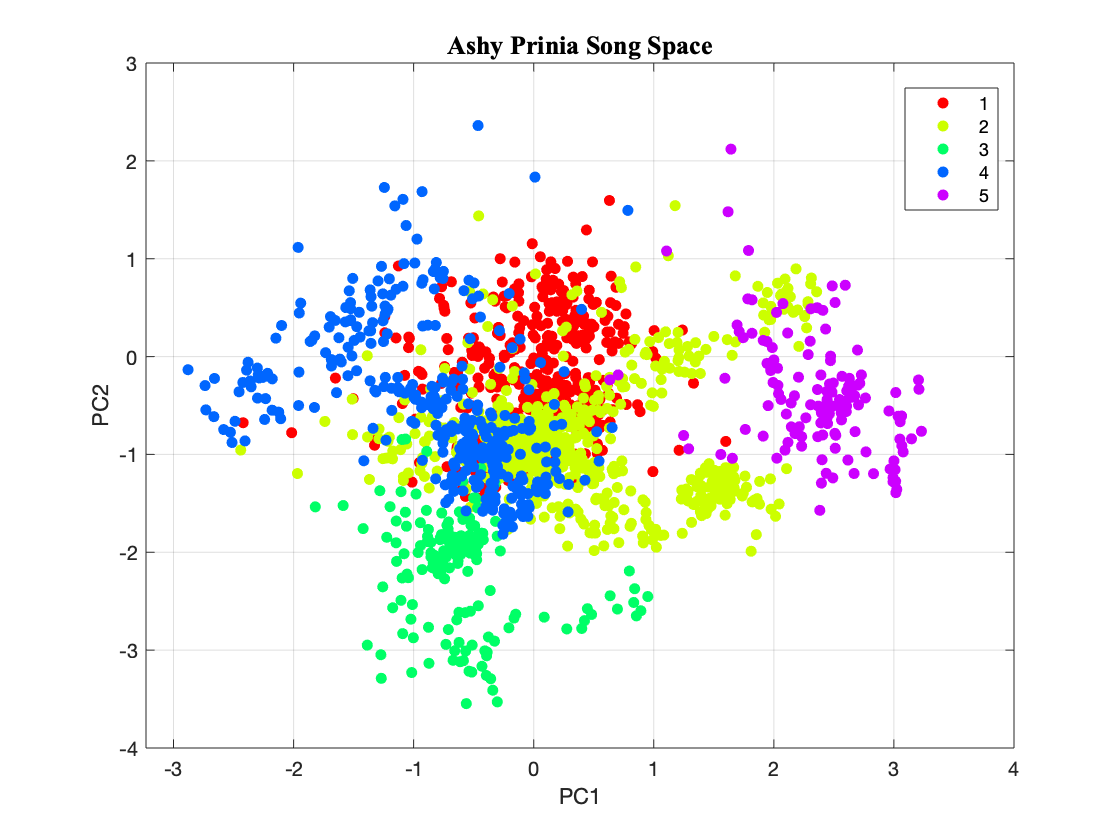

clua = cluster_data(scorea,5); %clusters data using 'ward' method and euclidean metric
%note that the clustering algorithm is run on the PC scores of ashy prinia notes (PCA done
%on the whole dataset which includes other prinia notes)

gscatter(scorea(:,1),scorea(:,2),clua,hsv(length(unique(clua))),[],15);
xlabel('PC1'); ylabel('PC2');
grid on;
title('Ashy Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

Plotting confusion matrix of the obtained clusters and the clustering done visually

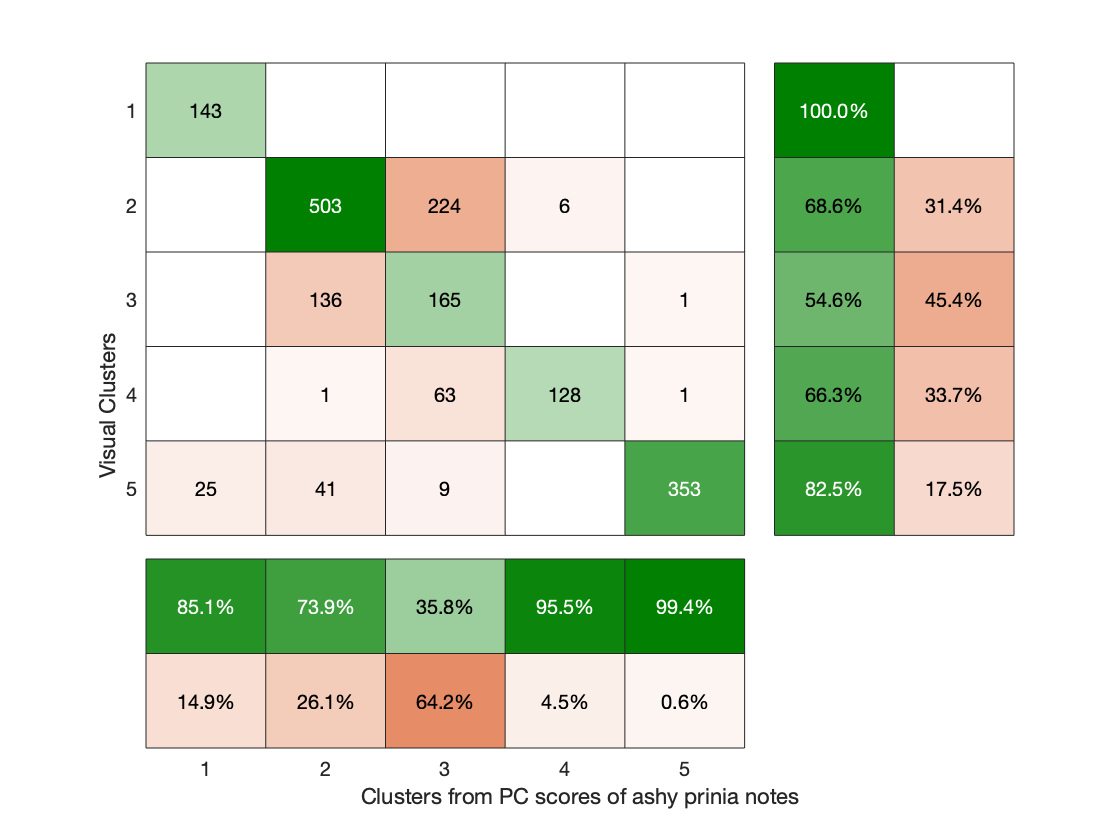

%looks like we need to align our clusters (we can do this visually) by
%looking at the colours in the two graphs
clua(clua==4) = 50; clua(clua==3) = 10; clua(clua==5) = 40; clua(clua==2) = 20; clua(clua==1) = 30; clua = clua./10;
confusionchart(Ta,clua,'DiagonalColor',...
    [0 0.5 0],'RowSummary',"row-normalized",'ColumnSummary',"column-normalized");
xlabel('Clusters from PC scores of ashy prinia notes'); ylabel('Visual Clusters');

**PCA on the Ashy Prinia dataset**

An alternative tactic is to perform a PCA on the ashy prinia raw dataset. This will allow us to visualise clusters better. 

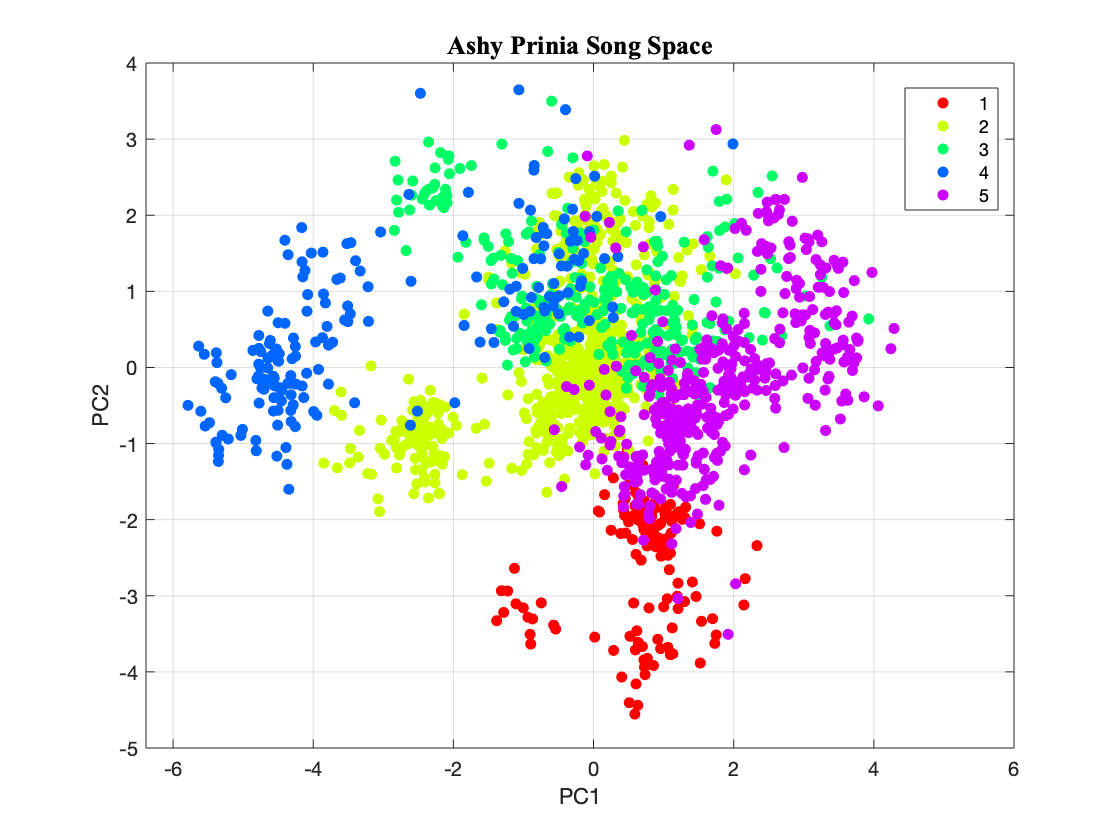

[~, score_a, ~, ~] = pcacorr(labelled_song_data(labelled_song_data(:,end)==1,1:end-1));
gscatter(score_a(:,1),score_a(:,2),Ta,hsv(length(unique(Ta))),[],15);
xlabel('PC1'); ylabel('PC2');
grid on;
title('Ashy Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

*Note:* Performing hierarchical clustering on scores obtained by performing PCA on ashy prinia space give similar results to clustering performed on scores of the ashy prinia notes obtained by performing PCA on whole dataset

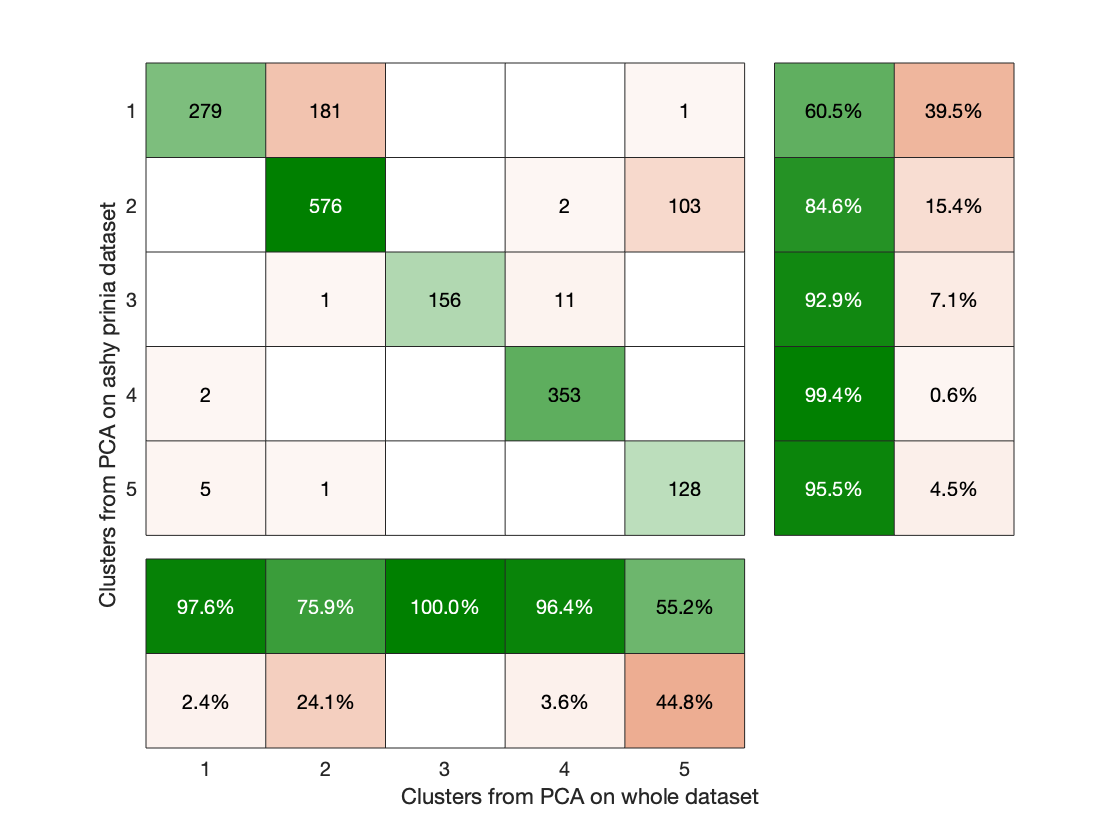

clua_pc_2 = cluster_data(score_a,5); clua_pc_1 = cluster_data(scorea,5);
confusionchart(clua_pc_1,clua_pc_2,'DiagonalColor',...
    [0 0.5 0],'RowSummary',"row-normalized",'ColumnSummary',"column-normalized");
xlabel('Clusters from PCA on whole dataset'); ylabel('Clusters from PCA on ashy prinia dataset');

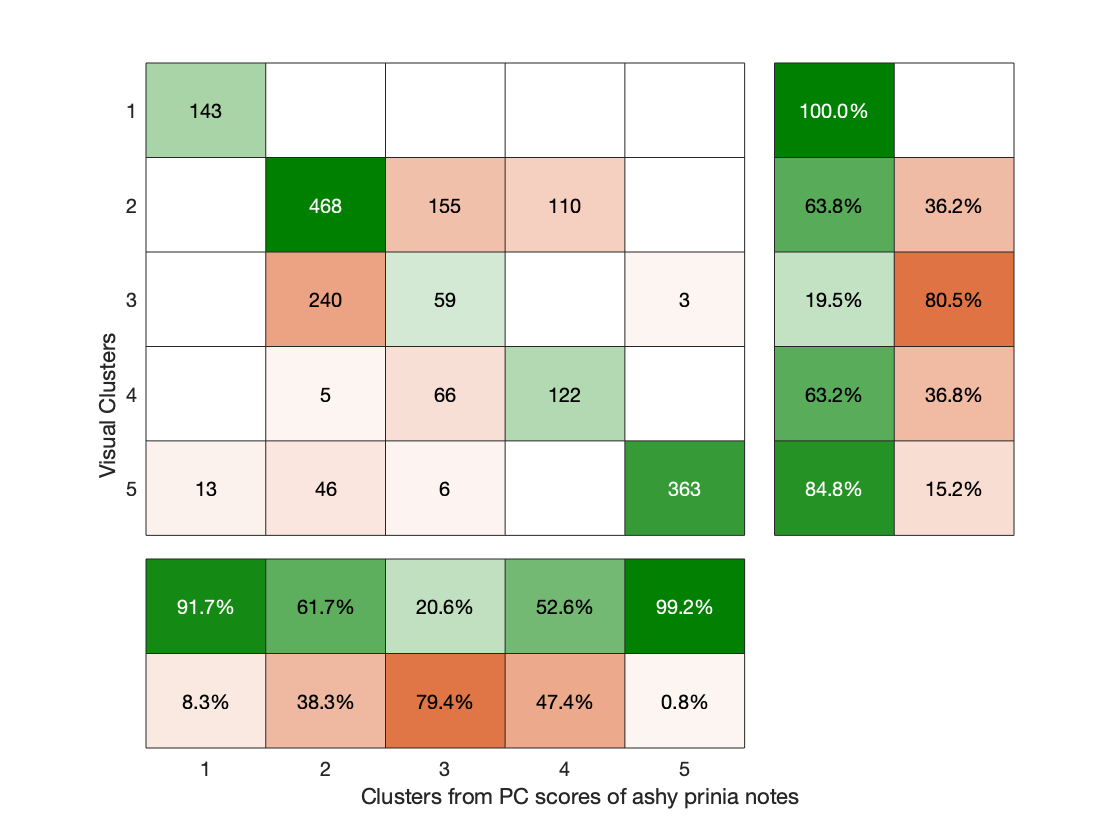

clua_pc_2(clua_pc_2==4) = 50; clua_pc_2(clua_pc_2==3) = 10; clua_pc_2(clua_pc_2==5) = 40; ...
    clua_pc_2(clua_pc_2==2) = 20; clua_pc_2(clua_pc_2==1) = 30; clua_pc_2 = clua_pc_2./10;
confusionchart(Ta,clua_pc_2,'DiagonalColor',...
    [0 0.5 0],'RowSummary',"row-normalized",'ColumnSummary',"column-normalized");
xlabel('Clusters from PC scores of ashy prinia notes'); ylabel('Visual Clusters');

*Suggestion:* Perform a PCA on a mono-species (sub)dataset for visualising purposes only

**Final Note Types and Visualization**

We use a function grouper which uses maximum overlap between annotated clusters and hierarchical clusters to give a final note type classification. 

This ensures that our original annotation is retained but the overall clustering takes into account the hierarchical classification. 

*Note: *using grouper on hierarchical clusters from PCA on ashy prinia dataset or on the visual clusters gives the same result. This indicates that all classifications are essentially similar! 

We visualise the note space as the PC-space of the ashy prinia (sub)dataset

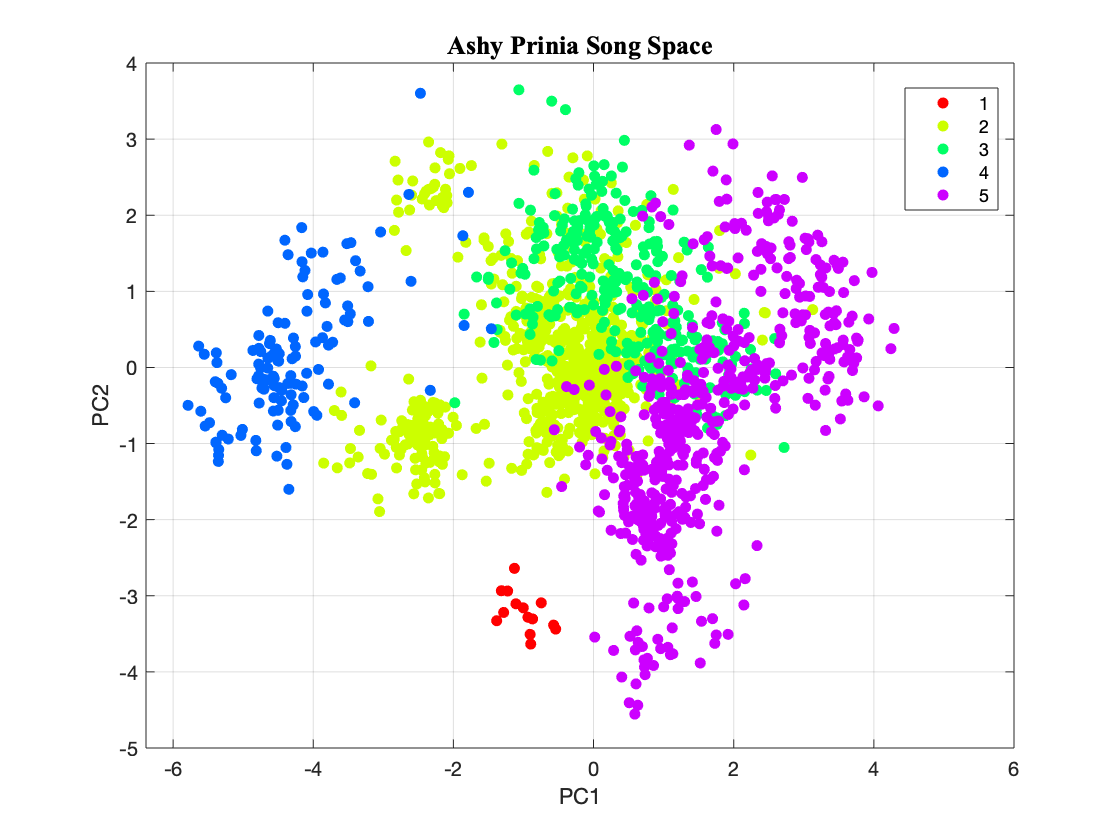

clf;
[~,fNTa] = grouper(songNTa,clua); %[~,fNTa] = grouper(songNTa,clua_pc_2); [~,fNTa] = grouper(songNTa,Ta);
gscatter(score_a(:,1),score_a(:,2),fNTa,hsv(length(unique(Ta))),[],15);
xlabel('PC1'); ylabel('PC2');
grid on;
title('Ashy Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

### **Grey Breasted Prinia Note Space**

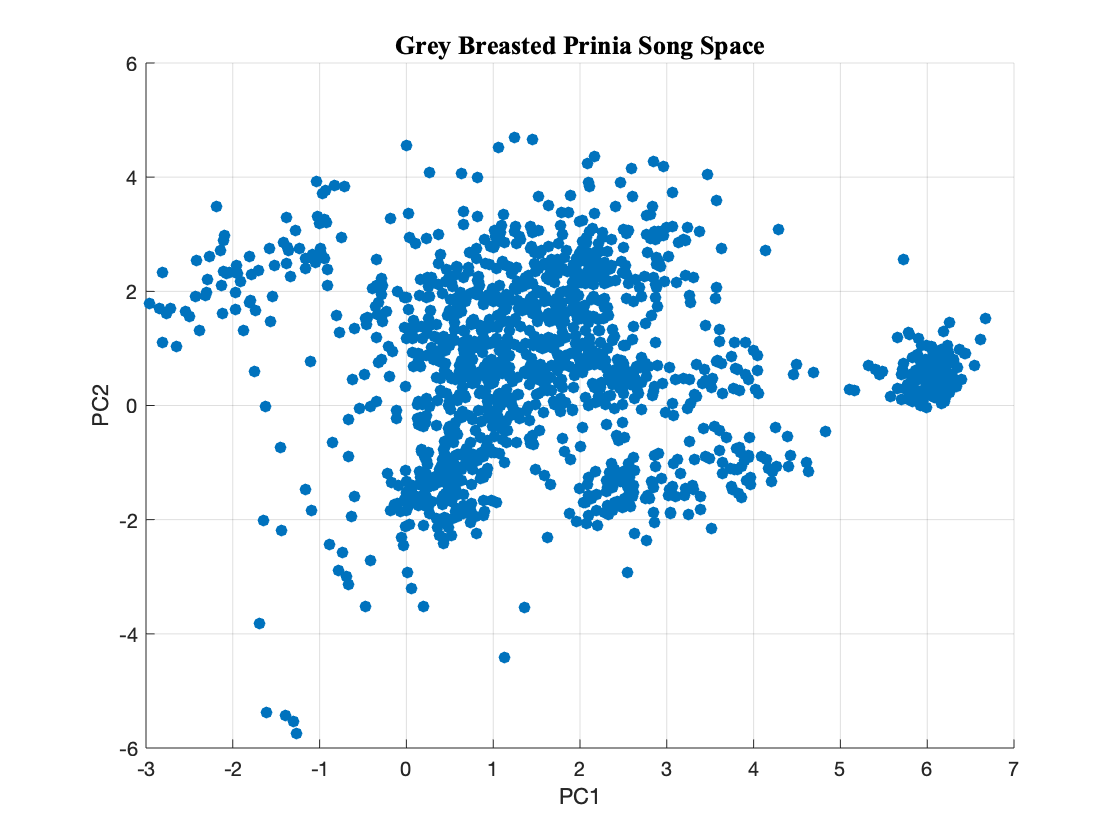

scatter(scoreg(:,1),scoreg(:,2), 'filled');
xlabel('PC1'); ylabel('PC2');
grid on;
title('Grey Breasted Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

**Annotated Clusters**

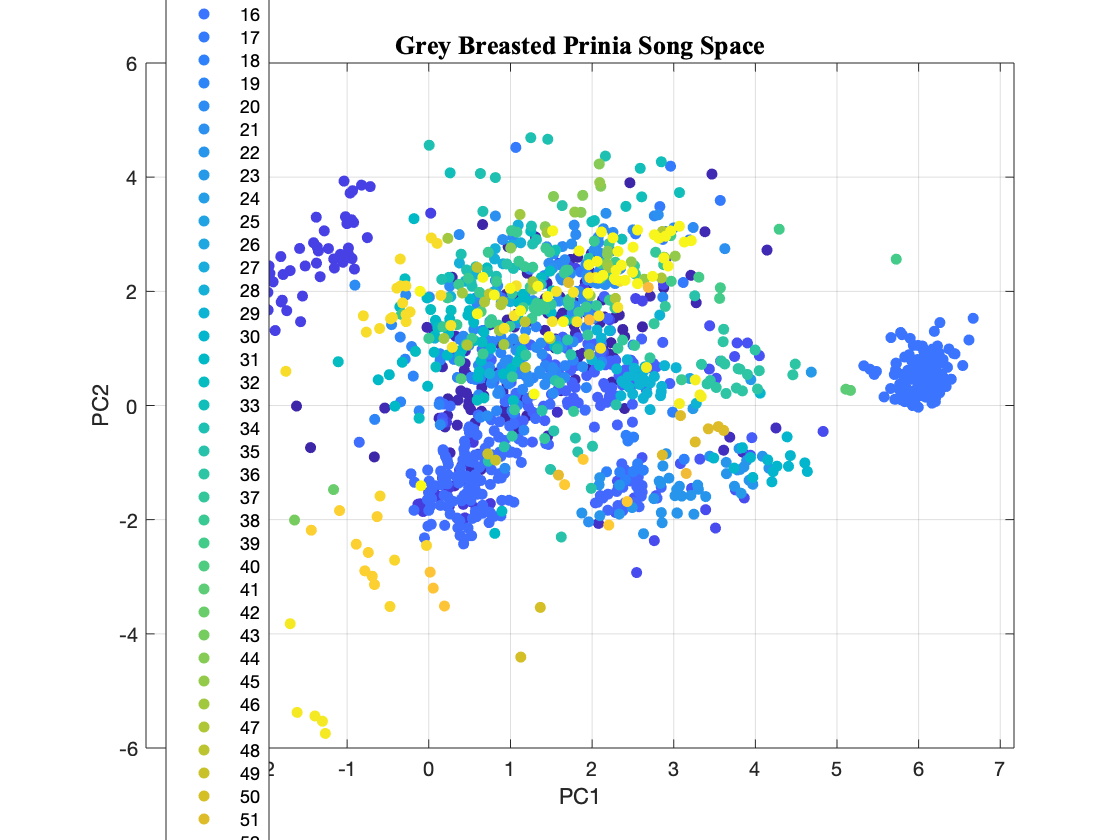

songNTg = indexer(songNTg);
gscatter(scoreg(:,1),scoreg(:,2),songNTg,parula(length(unique(songNTg))),[],15);
xlabel('PC1'); ylabel('PC2');
grid on;
title('Grey Breasted Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

**Visual Clustering**

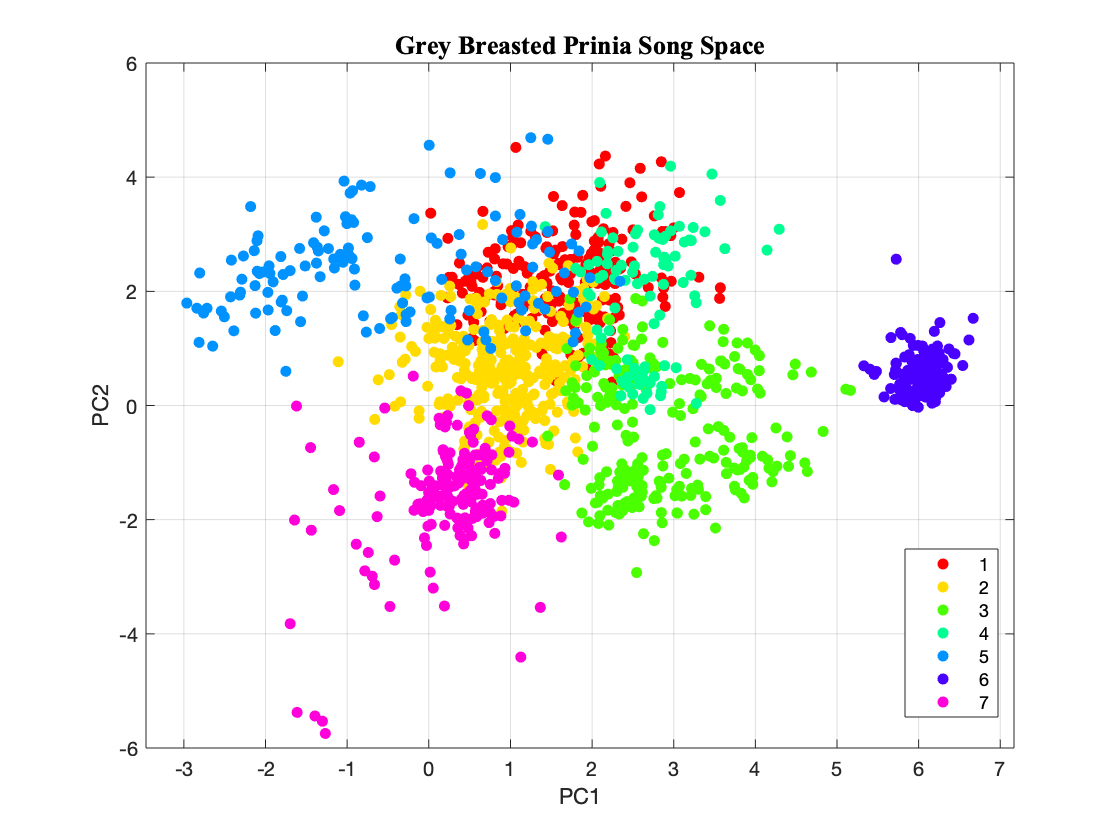

gscatter(scoreg(:,1),scoreg(:,2),Tg,hsv(length(unique(Tg))),[],15);
xlabel('PC1'); ylabel('PC2');
grid on;
title('Grey Breasted Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

**Hierarchical Clustering**

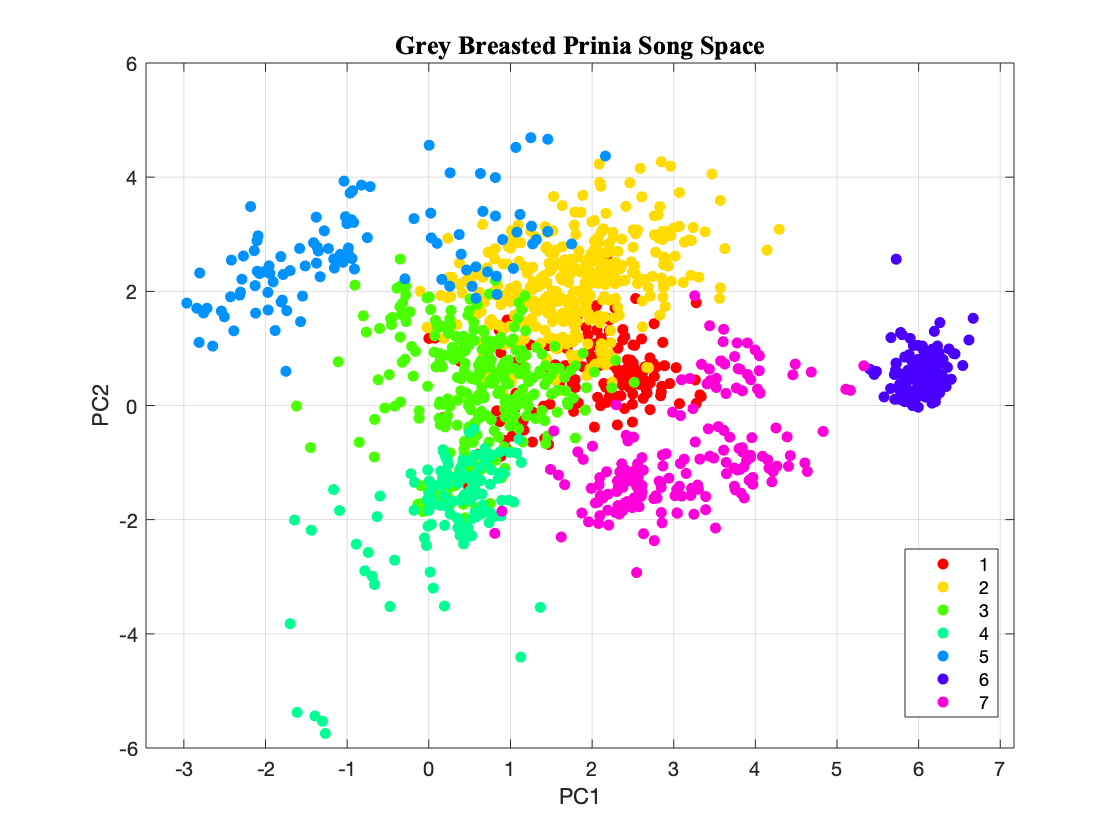

clug = cluster_data(scoreg,7);
gscatter(scoreg(:,1),scoreg(:,2),clug,hsv(length(unique(clug))),[],15);
xlabel('PC1'); ylabel('PC2');
grid on;
title('Grey Breasted Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

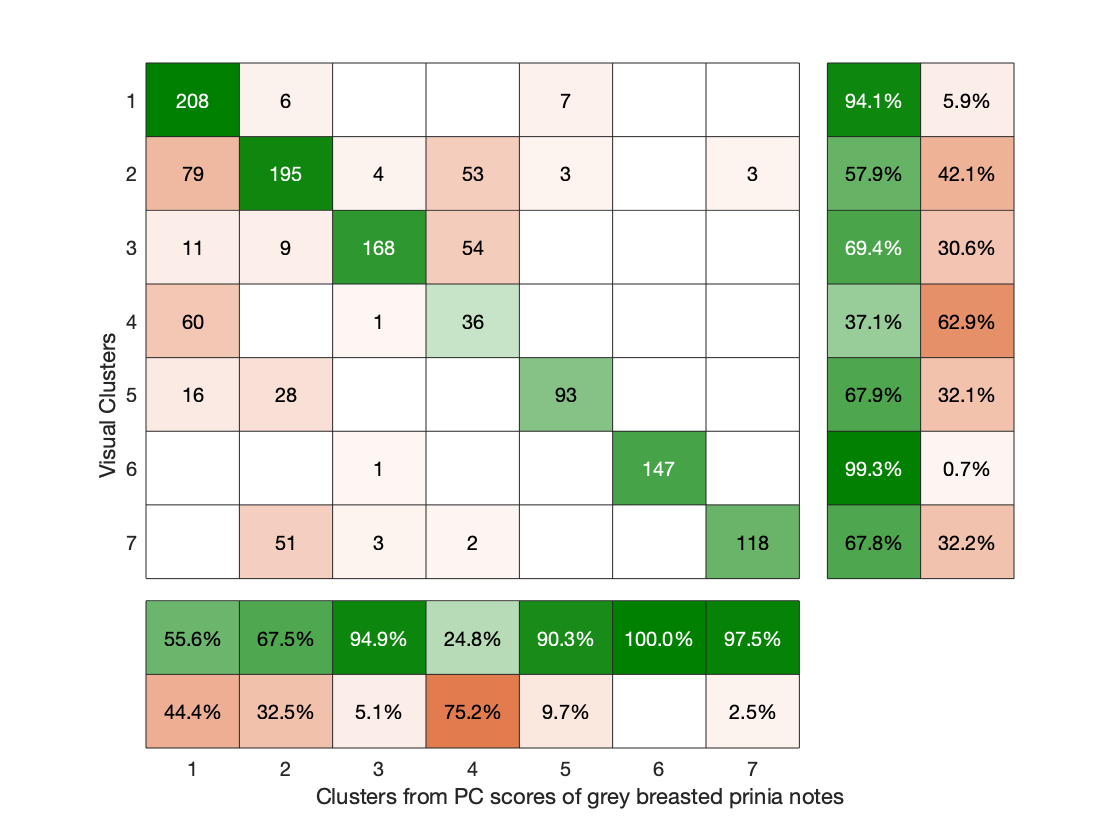

clug(clug==4) = 70; clug(clug==3) = 20; clug(clug==5) = 50; clug(clug==2) = 10; ...
    clug(clug==1) = 40; clug(clug==6) = 60; clug(clug==7) = 30; clug = clug./10;
confusionchart(Tg,clug,'DiagonalColor',...
    [0 0.5 0],'RowSummary',"row-normalized",'ColumnSummary',"column-normalized");
xlabel('Clusters from PC scores of grey breasted prinia notes'); ylabel('Visual Clusters');

**Final Note Types and Visualization**

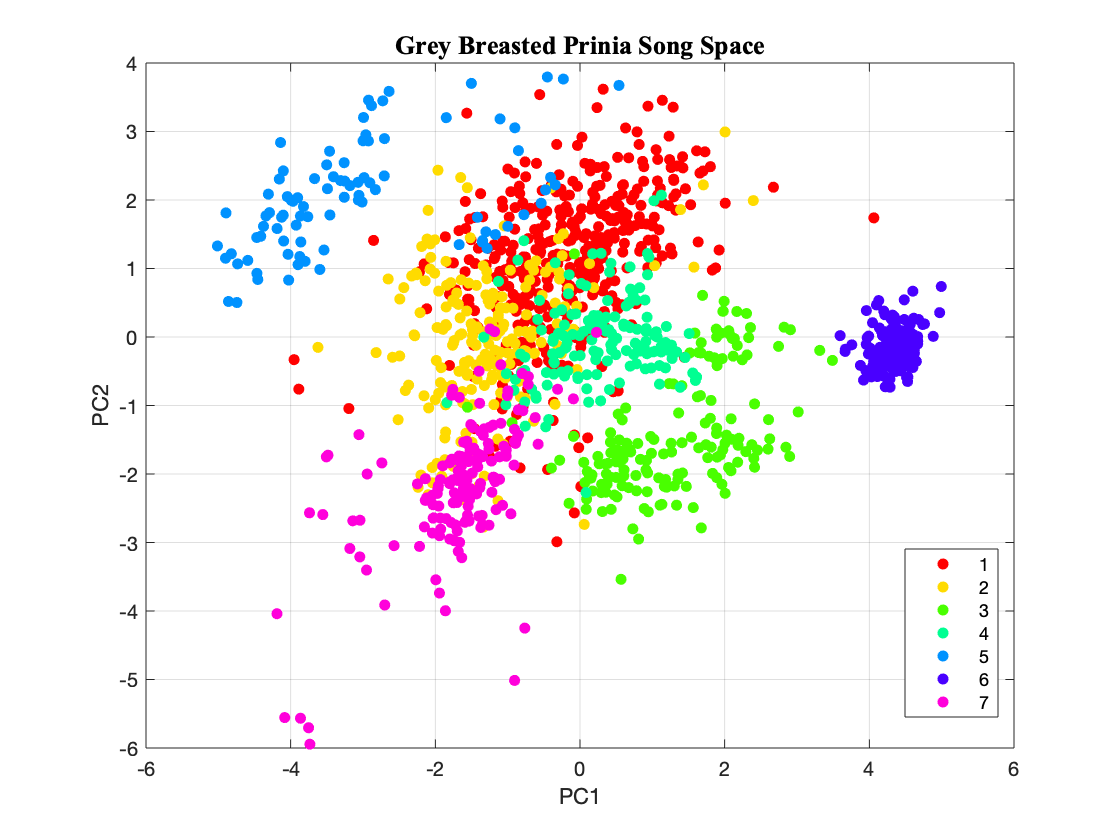

clf;
[~, score_g, ~, ~] = pcacorr(labelled_song_data(labelled_song_data(:,end)==2,1:end-1));
%clug_pc_2 = cluster_data(score_g,7);
%clug_pc_2(clug_pc_2==4) = 50; clug_pc_2(clug_pc_2==3) = 10; clug_pc_2(clug_pc_2==5) = 40; ...
% clug_pc_2(clua_pc_2==2) = 20; clug_pc_2(clua_pc_2==1) = 30; clug_pc_2 = clug_pc_2./10;
[~,fNTg] = grouper(songNTg,clug); %[~,fNTg] = grouper(songNTg,clug_pc_2); [~,fNTg] = grouper(songNTg,Tg);
gscatter(score_g(:,1),score_g(:,2),fNTg,hsv(length(unique(Tg))),[],15);
xlabel('PC1'); ylabel('PC2');
grid on;
title('Grey Breasted Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

### **Plain Prinia Note Space**

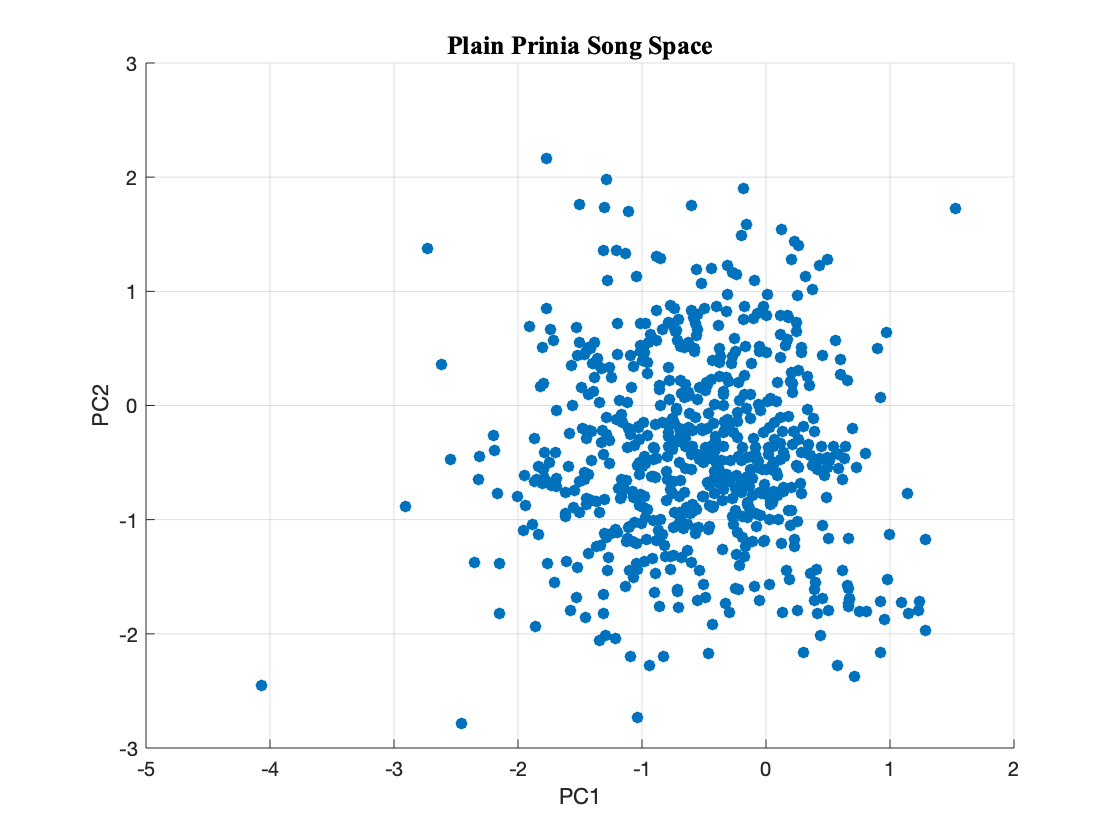

scatter(scorep(:,1),scorep(:,2), 'filled');
xlabel('PC1'); ylabel('PC2');
grid on;
title('Plain Prinia Song Space',"FontSize",13,'FontName','Times New Roman')

### **Jungle Prinia Note Space**

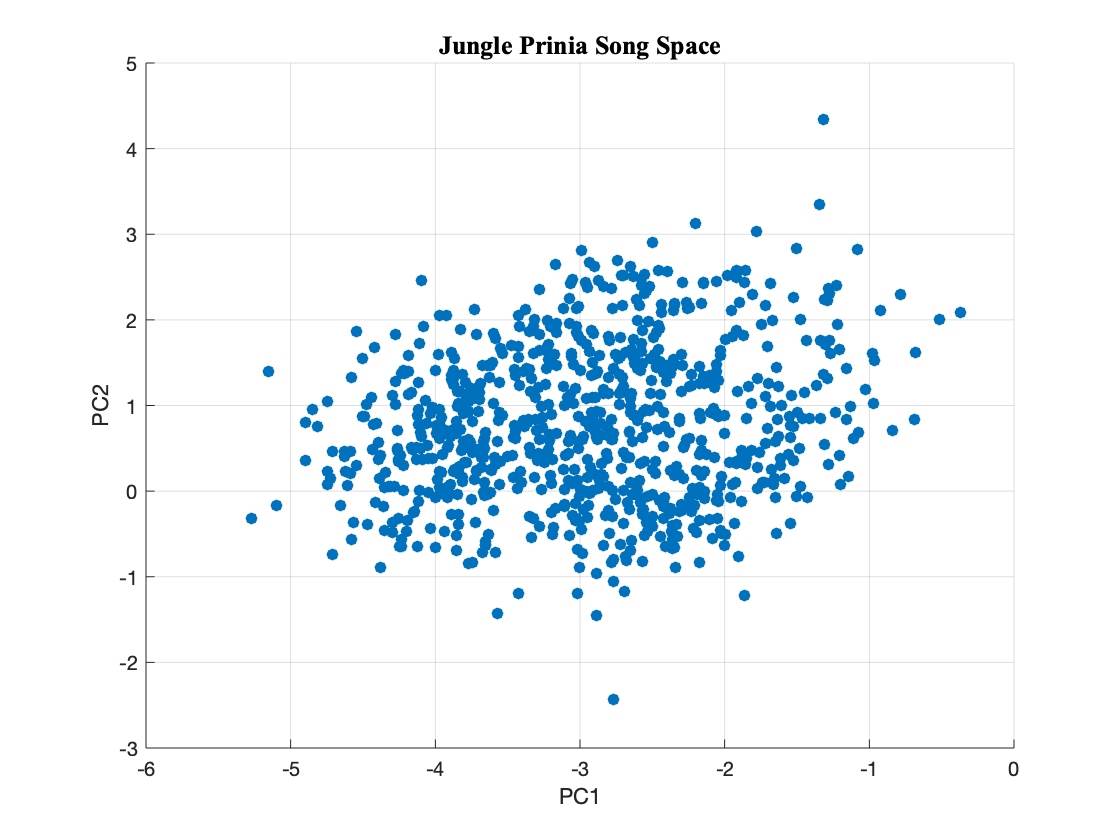

scatter(scorej(:,1),scorej(:,2), 'filled');
xlabel('PC1'); ylabel('PC2');
grid on;
title('Jungle Prinia Song Space',"FontSize",13,'FontName','Times New Roman')